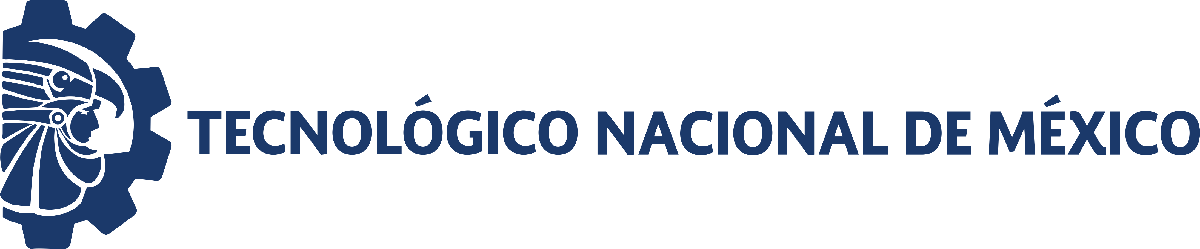                                 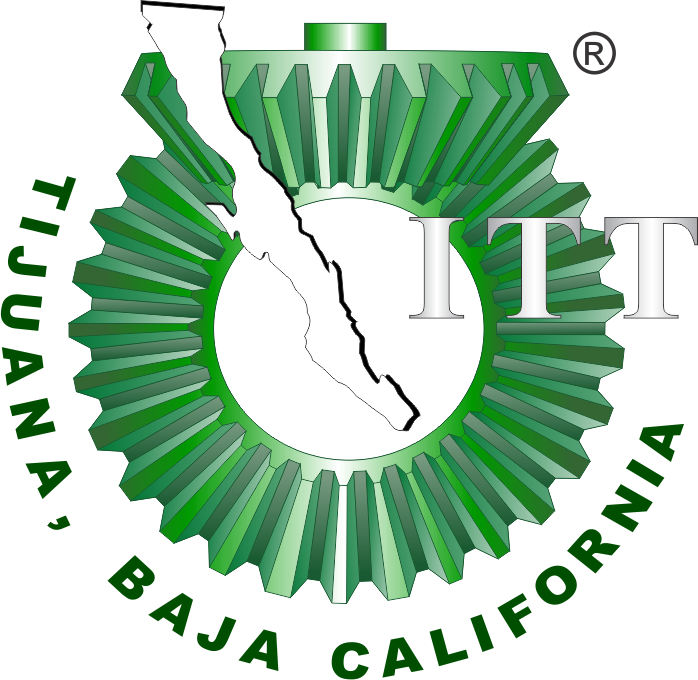

# Práctica 4: Modelizado matemático 

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

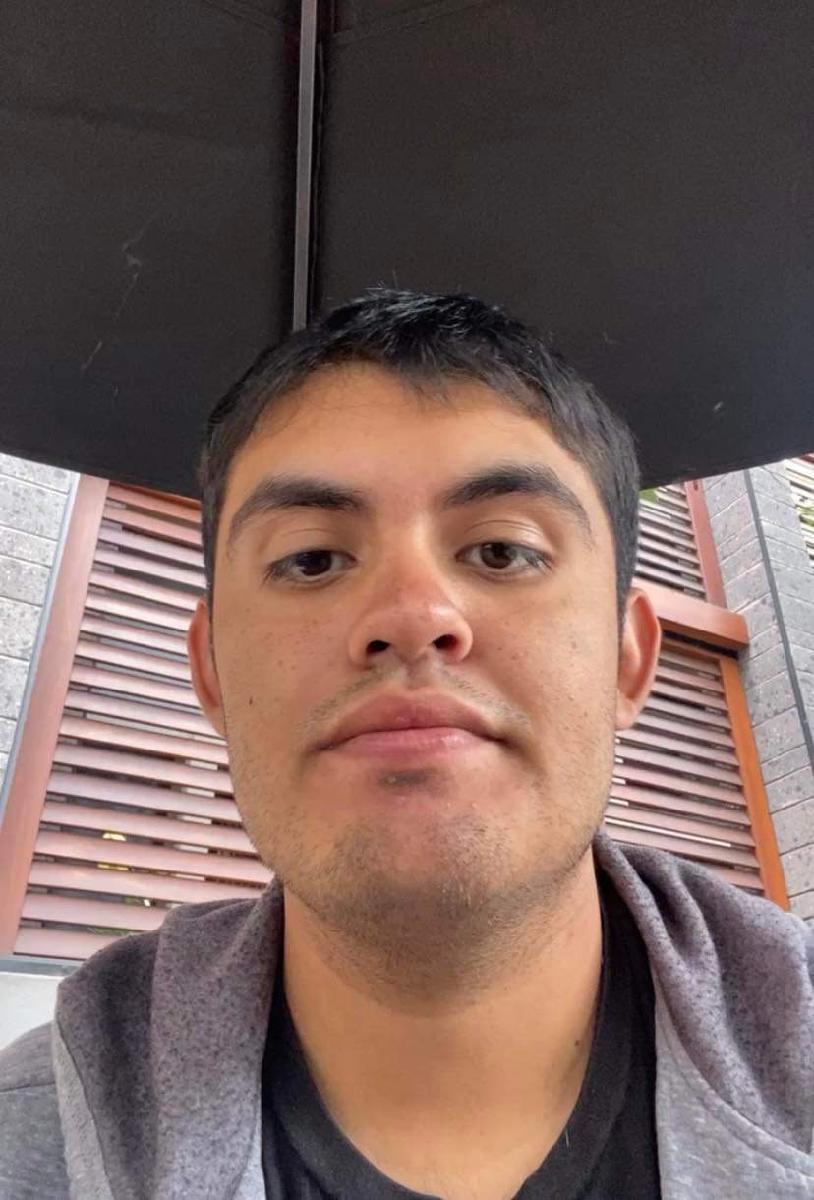

Nombre del alumno: **Andres Martin Bañuelos Elias**

Número de control: **21212142**

Correo institucional: **l21212142@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **References**

*[1]Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: *[*https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf*](https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf)

*[2] J. Nagy, Dynamics of Cancer: Mathematical Foundations of Oncology. Wordaz, 2014.*

*[3]R. A. Gatenby, "Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies," Cancer Research, vol. 63, no. 19, pp. 6212-6220, 2003.*

## Simulation Data

sys = readmatrix('data.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
T = array2table([to,xo,yo],'VariableNames',{'Time','x(t)','y(t)'});
disp(T)

    Time     x(t)       y(t)  
    ____    _______    _______

      0     0.83086    0.99501
      5       1.662     2.5145
     10      2.2956     4.8358
     15       2.837     6.9758
     20      3.9255     6.9853
     25      3.9262     7.2348
     30      4.7409     6.7614
     35      4.5751     6.3823
     40      5.2588     6.3545
     45      5.1664     6.1724
     50      5.8318     6.0549
     55       6.006     4.8586
     60      5.8311     5.5353
     65      5.8493      5.113
     70      6.5819     5.3388
     75      6.8798     4.7416
     80      6.3799     4.5736
     85      6.8302     4.7893
     90      6.6908     4.1221
     95      7.1671     4.3096
    100      7.1736     4.6394
    105      6.6341      4.249
    110      7.3832      4.463
    115      7.5585     4.3067
    120      7.1246     4.1103
    125      7.5308     3.7325
    130      7.2664     4.118

plotdata(to,xo,yo)

## Mathmeatical Models 

**Article: Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies**


$$\frac{dN_n }{\textrm{dt}}=R_n \left(1-\frac{N_N +\alpha_{\textrm{NT}} N_T }{K_n }\right)N_N$$



$$\frac{dN_T }{\textrm{dt}}=R_T \left(1-\frac{N_T +\alpha_{\textrm{TN}} N_N }{K_T }\right)N_T$$


RN & RT: are the maximum growth rates of normal and tumor cells, respectively. These rates result from the combination of tumor cell duplication and cell loss due to apoptosis or necrosis.

Kn & KT: represent the maximum cell densities for normal and tumor cells.

$\alpha$NT & $\alpha$TN: are the competition coefficients.

P0 = [0.1;0.1;0.1;0.1];
mdl = fitting_model(to,xo,yo,P0);

    Parameters    Estimate       SE          MoE              CI95             Pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053858    0.010722    0.14193    0.16337    8.0468e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3469e-62
      rho2        0.27411      0.011136     0.02217    0.25194    0.29628    1.6093e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371     9.992e-84

Degrees of freedom: 78
t-Student value: 1.9908
R-squared: 0.9742
AIC adjusted: 25.3575
Carrying capacity: 10

par = table2array(mdl.Coefficients(:,1));
rho1 = par(1); gamma1 = par(2); rho2 = par(3); gamma2 = par(4); beta = 10;
fa = mdl.Fitted;  fxy = reshape(fa,[],2);
xa = fxy(:,1); ya = fxy(:,2);
plotresults(to,[xo,xa],[yo,ya])

## Equilibrium points and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y rho1 rho2 gamma1 gamma2 beta
dx = rho1*x*(1 - (x + gamma1*y)/beta);
dy = rho2*y*(1 - (y + gamma2*x)/beta);
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix :'); disp(J)

Jacobian matrix :

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$

dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.']);

The Lotka-Volterra system has 4 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
X2 = edos.x(3); Y2 = edos.y(3);
X3 = edos.x(4); Y3 = edos.y(4);
syms x0 y0 x1 y1 x2 y2 x3 y3
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3]);

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$

clear gamma1 gamma2 beta
gamma1 = 0.67149;
gamma2 = 0.82706;
beta = 10;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(beta),',',num2str(0),')']); disp(['(x2,y2) = (', num2str(0),',',num2str(beta),')']); disp(['(x3,y3) = (', num2str(beta * (gamma1 - 1) / (gamma1 * gamma2 - 1)),',',num2str(beta * (gamma2 - 1) / (gamma1 * gamma2 - 1)),')'])

(x0,y0) = (0,0)
(x1,y1) = (10,0)
(x2,y2) = (0,10)
(x3,y3) = (7.3883,3.8895)


## Local estability

clc; clear; close all; warning('off','all')
gamma1 = 0.67149; gamma2 = 0.82706;
rho1 = 0.15265; rho2 = 0.27411;
beta = 10;
syms x y
dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
x2 = double(edos.x(3)); y2 = double(edos.y(3));
x3 = double(edos.x(4)); y3 = double(edos.y(4));
clear x y
x = [x0;x1;x2;x3]; y = [y0;y1;y2;y3];
var = {'(x0,y0)';'(x1,y1)';'(x2,y2)';'(x3,y3)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
L = zeros(length(x),2);
for i = 1:length(x)
     J = [-rho1 * ((x(i) + gamma1 * y(i)) / beta - 1) - rho1 * x(i) / beta, -rho1 * x(i) * gamma1 / beta;
         -rho2 * y(i) * gamma2 / beta, -rho2 * ((y(i) + gamma2 * x(i)) / beta - 1) - rho2 * y(i) / beta]
     L(i,:) = eig(J);
end

J =     0.1527         0
         0    0.2741


J =    -0.1527   -0.1025
         0    0.0474


J =     0.0501         0
   -0.2267   -0.2741


J =    -0.1128   -0.0757
   -0.0882   -0.1066


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1          L2    
               ________    _________

    (x0,y0)     0.15265      0.27411
    (x1,y1)    -0.15265     0.047405
    (x2,y2)    -0.27411     0.050147
    (x3,y3)    -0.19147    -0.027922



Considering the values of the Jacobian matrix evaluated at each equilibrium point of the system, the following conclusions can be drawn: the point (x0,y0)(x_0, y_0)(x0�,y0�) is an unstable source node, as its eigenvalues are real and positive. The points (x1,y1)(x_1, y_1)(x1�,y1�) and (x2,y2)(x_2, y_2)(x2�,y2�) correspond to saddle points, with eigenvalues of opposite signs, indicating that they are also unstable. On the other hand, the point (x3,y3)(x_3, y_3)(x3�,y3�) is a stable sink node, with both eigenvalues negative. Thus, the system has a single locally stable region, while multiple points exhibit unstable behavior. In nonlinear systems like this one, local stability can be determined by linearizing around the equilibrium points. However, when the eigenvalues have a zero real part or are complex, additional methods, such as Lyapunov’s criterion or the LaSalle invariance principle, should be employed for a more detailed and rigorous analysis.

## Equilibrium Points Graphics

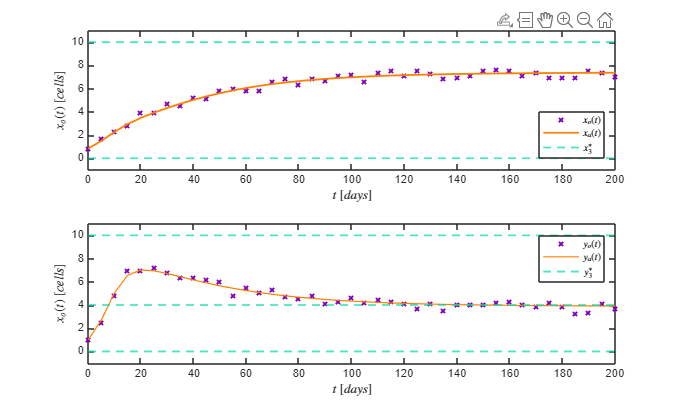

clc; clear; close all;
sys = readmatrix('data.csv');
to = sys(:,1); 
xo = sys(:,2); 
yo = sys(:,3);
rho1 = 0.15265; gamma1 = 0.67149; 
rho2 = 0.27412; gamma2 = 0.82706;
P0 = [rho1,gamma1,rho2,gamma2];
[mdl, xa, ya] = Variant(to,xo,yo,P0); 
plotchido(to,[xo,xa],[yo,ya])

## Plot data 

function plotchido(to, xo, yo)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    set(gca, 'FontSize', 12)  
    
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(to, xo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(to, xo(:,2), '-', 'LineWidth', 1.5, 'Color', c2)
    yline(10, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(0, '--', 'LineWidth', 1.5, 'Color', c3)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$ $[cells]$', 'Interpreter', 'latex')
    L = legend('$x_o(t)$', '$x_a(t)$', '$x^*_3$');
    set(L, 'Interpreter', 'latex', 'Location', 'Best', 'Box', 'On')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(to, yo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(to, yo(:,2), '-', 'LineWidth', 1, 'Color', c2)
    yline(10, '--', 'LineWidth', 1.5, 'Color', c3)
        yline(0, '--', 'LineWidth', 1.5, 'Color', c3)
    yline(4, '--', 'LineWidth', 1.5, 'Color', c3)

    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$ $[cells]$', 'Interpreter', 'latex')
    L = legend('$y_o(t)$', '$y_a(t)$', '$y^*_3$');
    set(L, 'Interpreter', 'latex', 'Location', 'Best', 'Box', 'On')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)
end

## Plot data 

function plotdata(to, xo, yo)
    set(figure(), 'Color', 'w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,25,10])

    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 2); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
   
    subplot(2,1,1)
    plot(to, xo, '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c1)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$x_o(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)

    subplot(2,1,2)
    plot(to, yo, '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c2)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$y_o(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    
    sgtitle('Experimental data', 'FontSize', FS + 2, 'FontWeight', 'bold');
    
    saveas(gcf, 'Experimental Data.png')
end

## Illustrate approximate data

function plotresults(to, xo, yo)
    set(figure(), 'Color', 'w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 25, 10])

    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;
        0.75, 1.00, 0.00;
        0.00, 0.75, 1.00;
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;
        0.40, 0.20, 0.10;
        1.00, 0.00, 0.80;
        1.00, 0.85, 0.00;
        0.00, 0.85, 0.65;
        0.30, 0.45, 0.60
    ];
    rng('shuffle');
    indices = randperm(size(Mecambiareaindustrial, 1), 4); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);
    c4 = Mecambiareaindustrial(indices(4), :);

    subplot(2,1,1)
    plot(to, xo(:,1), '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c1)
    hold on
    plot(to, xo(:,2), '-', 'LineWidth', 1, 'Color', c2)
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$x_i(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    L = legend('$x_o(t)$', '$x_a(t)$');
    set(L, 'Interpreter', 'Latex', 'fontsize', FS, 'Location', 'SouthEast')
    set(gca, 'FontName', 'Times New Roman', 'Fontsize', FS)

    subplot(2,1,2)
    plot(to, yo(:,1), '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c3)
    hold on
    plot(to, yo(:,2), '-', 'LineWidth', 1, 'Color', c4)
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$y_i(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    L = legend('$y_o(t)$', '$y_a(t)$');
    set(L, 'Interpreter', 'Latex', 'fontsize', FS, 'Location', 'NorthEast')
    set(gca, 'FontName', 'Times New Roman', 'Fontsize', FS)
    
    saveas(gcf, 'plot_AproximalData.png')
end

## Functions Mathematical models

function mdl = fitting_model(to,xo,yo,P0)
fo = [xo;yo]; to = [to;to]; x0 = xo(1); y0 = yo(1); beta = 10;

    function xi = AjusteAproximado(P,t)
        t = reshape(t,[],2); t = t(:,1);
        rho1 = P(1); gamma1 = P(2); rho2 = P(3); gamma2 = P(4);
        dt = 1E-2;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = rho1*x*(1 - (x + gamma1*y) / beta);
            dy = rho2*y*(1 - (y + gamma2*x) / beta);
        end

        xi = zeros(length(t),1);  yi = zeros(length(t),1);
        for i = 1:length(t)
            k = abs(time-t(i)) < 1E-9; 
            xi(i) = x(k);
            yi(i) = y(k);
        end

        xi = [xi;yi];
    end

mdl = fitnlm(to, fo, @AjusteAproximado, P0);

Estimate = table2array(mdl.Coefficients(:, 1));
Pvalue = table2array(mdl.Coefficients(:, 4));
SE = table2array(mdl.Coefficients(:, 2));
CI95 = coefCI(mdl, 0.05);
dof = mdl.DFE;  
alpha = 0.05;   
tval = tinv(1 - alpha / 2, dof);  
MoE = SE * tval;  
car=10;
Parameters = ['rho1  '; 'gamma1'; 'rho2  '; 'gamma2'];

fit = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);

disp(fit)
R_squared = mdl.Rsquared.Ordinary; 
AIC = mdl.ModelCriterion.AIC; 
k = length(Estimate);  
n = length(to); 
AIC_adjusted = AIC + (2*k*(k+1))/(n-k-1);


fprintf('Degrees of freedom: %d\n', dof);  

fprintf('t-Student value: %.4f\n', tval);  

fprintf('R-squared: %.4f\n', R_squared);  

fprintf('AIC adjusted: %.4f\n', AIC_adjusted);

fprintf('Carrying capacity: %d',car);

end

Variant 

function [mdl,xa,ya] = Variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        rho1 = p(1); gamma1 = p(2); rho2 = p(3); gamma2 = p(4);
        dt = 1E-1;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = rho1*x*(1-((x+gamma1*y)/10));
            dy = rho2*y*(1-((y+gamma2*x)/10));
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1); ya = fx(:,2);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2';];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end